close all; clc

% find equilibrium points
syms a positive
syms b nonzero
syms x1 x2

% find equilibrium points
f1 = 2*x1 - x1*x2;
f2 = 2*x1^2 - x2;

sln = solve([f1==0, f2==0], [x1 x2]);
sln.x1

$$ans = \left(\begin{array}{c} 0\\ -1\\ 1 \end{array}\right)$$

sln.x2

$$ans = \left(\begin{array}{c} 0\\ 2\\ 2 \end{array}\right)$$

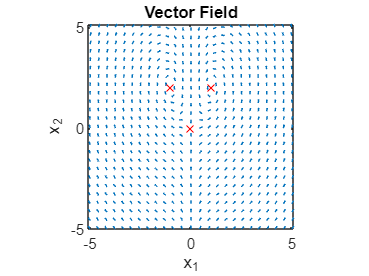

% Create vector field
x = linspace(-5,5,25);
y = linspace(-5,5,25);
[X,Y] = meshgrid(x,y);

DX = 2*X - X.*Y;
DY = 2*X.^2 - Y;

N = sqrt(DX.^2 + DY.^2);
quiver(X,Y,DX./N,DY./N,0.3);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

% draws x's on the real equilibrium points
hold on;
for i=1:numel(sln.x1)
    if isreal(sln.x1(i)) && isreal(sln.x2(i))
        plot(sln.x1(i), sln.x2(i), 'rx')
    end
end
hold off